## With G(wj) given

Gwj = -0.5;

N = -1/Gwj;
M = pi;

x0 = 4*M/(pi*N) %Amplitude 

## Q9 stuff

%Char poly - s^2 + Kds + Kp => Kd = 1.5 for 0.75 damp

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -8.27e-01 + 7.17e-01i     7.55e-01       1.09e+00         1.21e+00    
 -8.27e-01 - 7.17e-01i     7.55e-01       1.09e+00         1.21e+00    
 -8.35e+00                 1.00e+00       8.35e+00         1.20e-01    


Kd = 1.5;
Kp = 1;
s = tf('s');
act = 1/(0.1*s + 1);
ILTF = feedback(act/s,Kd);
CLTF = feedback(ILTF*Kp/s,1);
damp(CLTF)
%w = 1.09

[A,B,C,D] = linmod('exam');

sys = struct with fields:
             a: [3×3 double]
             b: [3×1 double]
             c: [-10 -15 -10]
             d: 0
     StateName: {3×1 cell}
    OutputName: {'exam2021/Outport'}
     InputName: {'exam2021/Inport'}
     OperPoint: [1×1 struct]
            Ts: 0


sys_s = ss(A,B,C,D);
damp(A)
%w = 1.09

From, exam1 - plot before saturation block.

xo=10.1

omega=2*pi/(13.7-6.9)=0.91

## Function stuff

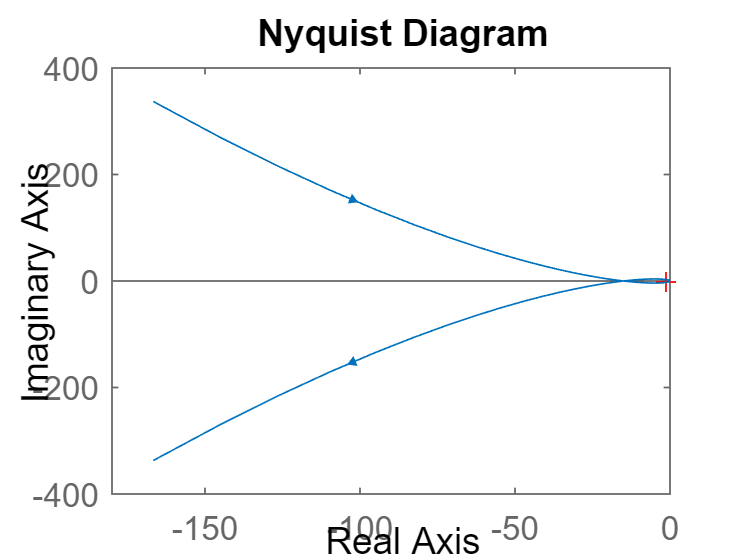

sys = linmod('exam2021')
A = sys.a;

B = sys.b;
C = sys.c;
D = sys.d;
nyquist(-ss(A,B,C,D))
%run in command window to zoom
%w = 1, intersects at -15


x0 = 9.5493

N = -1/-15;
L = 0.5;

x0 = 4*L/(pi*N) %Amplitude 

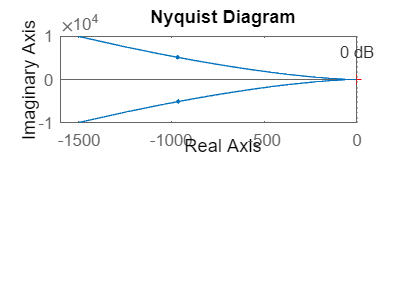

[A,B,C,D] = linmod('exam2');
sys_sat = -ss(A,B,C,D);

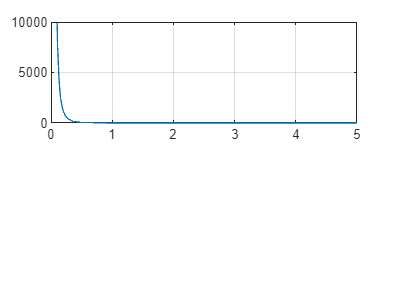

omega = 0.1:0.01:5;
nyquist(sys_sat,omega)
grid on;
[reG,imG] = nyquist(sys_sat,omega);

imG = squeeze(imG);
plot(omega,imG)
grid on;
%w = 1
N = -1/-14.2;

x0 = 9.0400

sys = struct with fields:
             a: [4×4 double]
             b: [4×1 double]
             c: [-10 -15 -10 -10]
             d: 0
     StateName: {4×1 cell}
    OutputName: {'exam2021_anti/Outport'}
     InputName: {'exam2021_anti/Inport'}
     OperPoint: [1×1 struct]
            Ts: 0


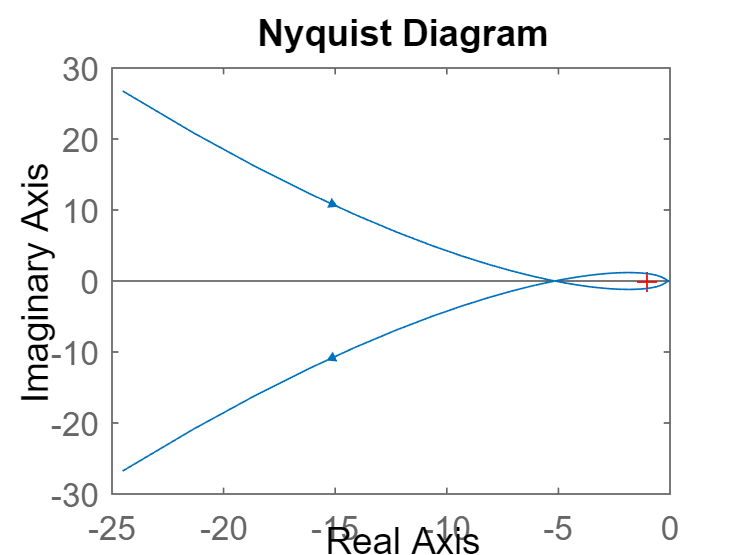

x0 = 3.3104

L = 0.5;


x0 = 4*L/(pi*N) %Amplitude 


In exam3_sat, we found new thetac =5.1, corresponding xo=3.6 and omega 2*pi/(17.8-7.6)=0.61

[A,B,C,D] = linmod('exam3');
sys_sat_cont = -ss(A,B,C,D);
nyquist(-ss(A,B,C,D))
%w = .67, intersects at -5.1

N = -1/-5.1;
L = 0.5;

x0 = 4*L/(pi*N) %Amplitude 